%% Requirements
% Image Processing Toolbox   (radon, iradon, phantom)
% Symbolic Math Toolbox      (for analytic section, optional)
% Medical Image Toolbox      (dicomCollection, dicomreadVolume) – optional
% Helper file `saveFig.m`    in the same directory.

%% Introduction
% In 1917 Johann Radon proved that a 2-D function can be reconstructed
% from its line integrals – the foundation of today’s computed tomography
% (CT).  This notebook:
%  1.  Works an analytic example with Symbolic Math Toolbox.
%  2.  Demonstrates discrete Radon / inverse Radon on images.
%  3.  Explores a real COVID-19 chest CT slice from the MosMedData set.
%
% Figures are auto-saved as PNGs for inclusion in a LaTeX report.

%% 1 · Analytic Radon Transform of a Gaussian
syms x y p phi s real
assumeAlso([x y p s],'real')

f = exp(-(x^2 + y^2));                       % f(x,y) = e^{-(x^2+y^2)}

expr = subs(f, {x,y}, {p*cos(phi)-s*sin(phi), ...
                        p*sin(phi)+s*cos(phi)});
R = simplify(int(expr, s, -inf, inf));       % symbolic Radon transform
fprintf("Radon of Gaussian:  R(p,phi) = %s\n\n", char(R))

Radon of Gaussian:  R(p,phi) = pi^(1/2)*exp(-p^2)



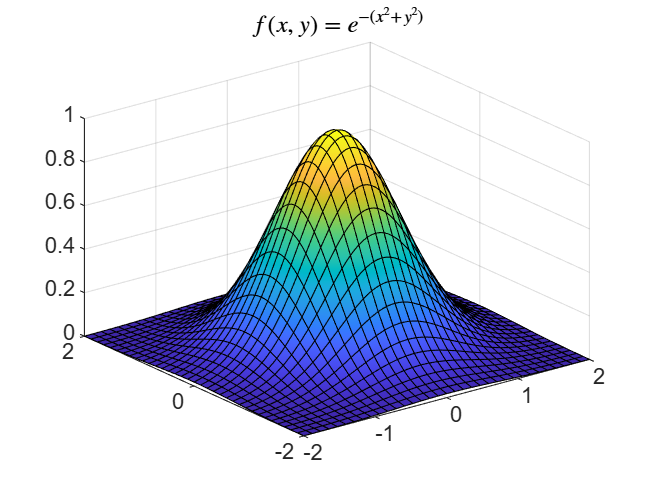


% 1a · 3-D surface of f
fHandle = matlabFunction(f,'Vars',{x y});
figure
fsurf(fHandle,[-2 2 -2 2]); shading interp
title('$f(x,y)=e^{-(x^2+y^2)}$','Interpreter','latex')
saveFig("gaussian_surface.png")

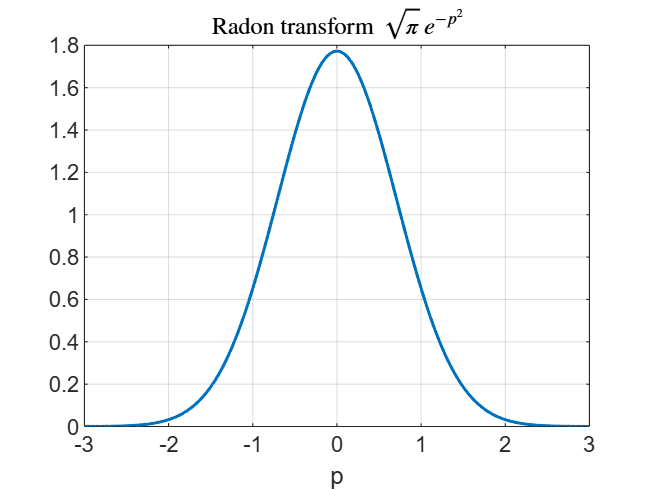


% 1b · Radon vs p
figure
pp   = linspace(-3,3,400);
Rfun = matlabFunction(R,'Vars',{p});          % numeric handle
plot(pp, Rfun(pp), 'LineWidth',1.4)
xlabel('p'); grid on
title('Radon transform  $\sqrt{\pi}\,e^{-p^{2}}$','Interpreter','latex')
saveFig("gaussian_radon.png")

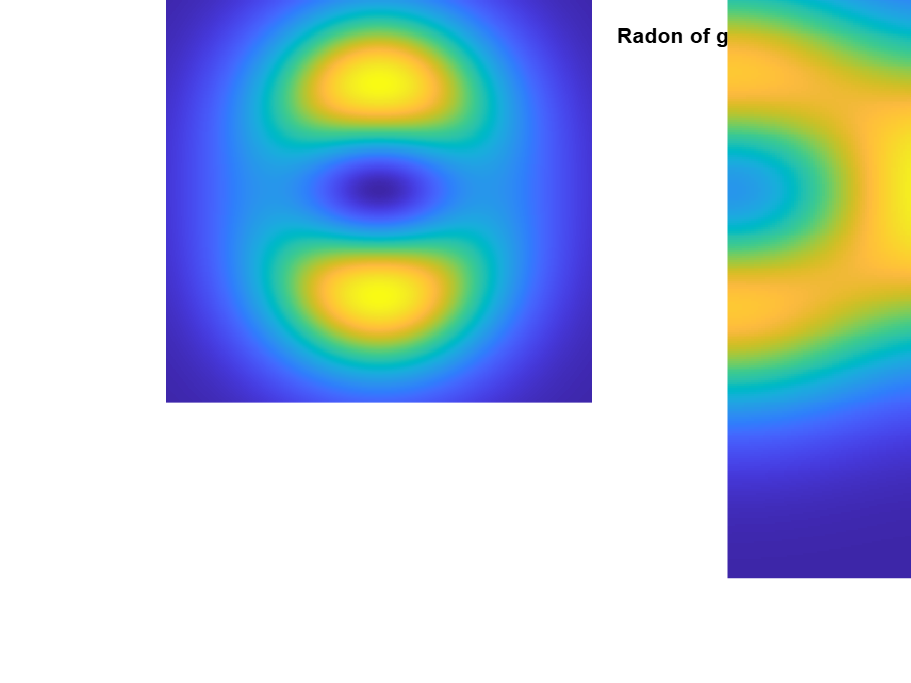


%% 2 · Asymmetric polynomial–Gaussian example
g = (x^2 + 3*y^2) .* exp(-(x^2 + y^2));      % g(x,y)
expr2 = subs(g, {x,y}, {p*cos(phi)-s*sin(phi), ...
                         p*sin(phi)+s*cos(phi)});
R2 = simplify(int(expr2, s, -inf, inf));

% Create numeric grids for plotting
[xv,yv] = meshgrid(linspace(-2,2,400));
Gnum = double(subs(g, {x y}, {xv,yv}));

phiVec = linspace(-pi/2, pi/2, 180);
pVec   = linspace(-3, 3,   400);
[PV,PHIV] = meshgrid(pVec, phiVec);
R2mat = double(subs(R2, {p phi}, {PV', PHIV'}));

figure
subplot(1,2,1)
imagesc(xv(1,:), yv(:,1), Gnum); axis image off
title('g(x,y)')
subplot(1,2,2)
imagesc(phiVec, pVec, R2mat); axis xy off
title('Radon of g')
saveFig("asymmetric_function_and_radon.png")

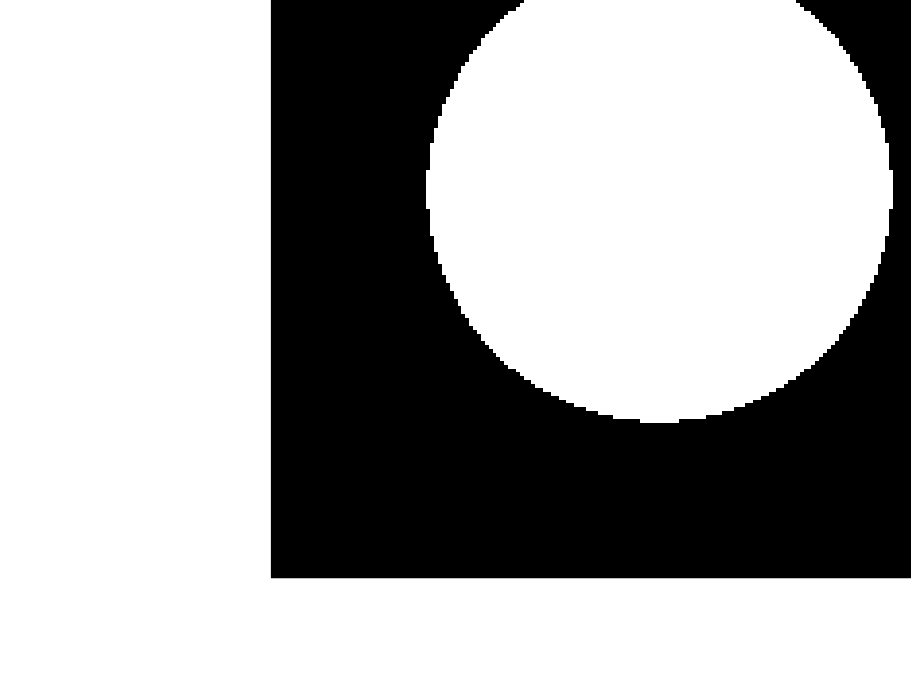


%% 3 · Binary disk phantom (parallel-beam CT)
N = 200;
[xg, yg] = meshgrid(linspace(-1,1,N));
diskImg  = hypot(xg,yg) <= 0.6;

figure, imshow(diskImg,[]), title('Binary disk phantom')
saveFig("disk_original.png")

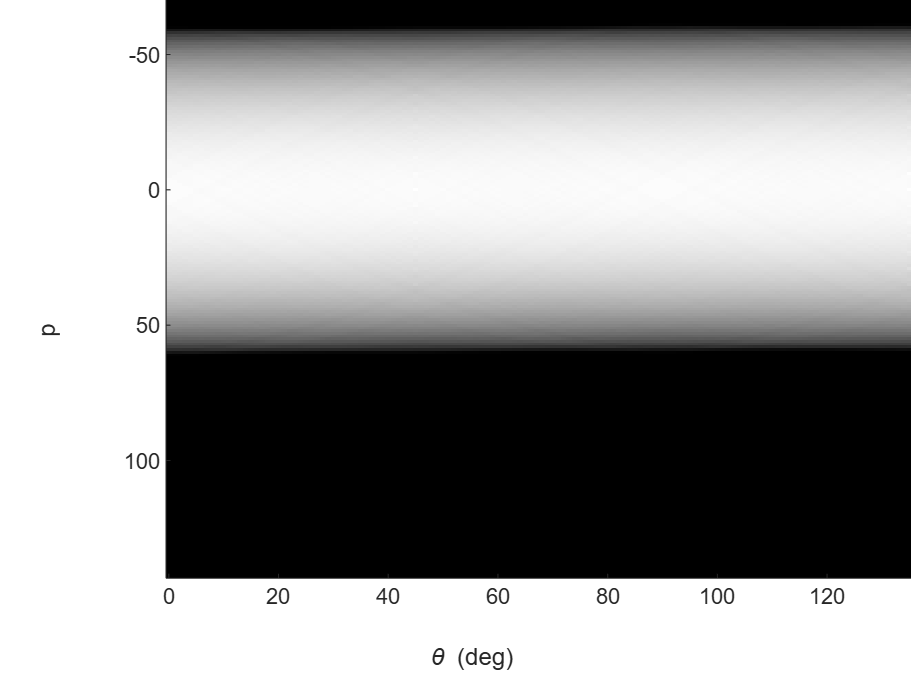


theta = 0:179;
[sinogram, xp] = radon(diskImg, theta);

figure
imagesc(theta, xp, sinogram); colormap(gray); axis tight
xlabel('\theta (deg)'), ylabel('p'), title('Disk sinogram')
saveFig("disk_sinogram.png")

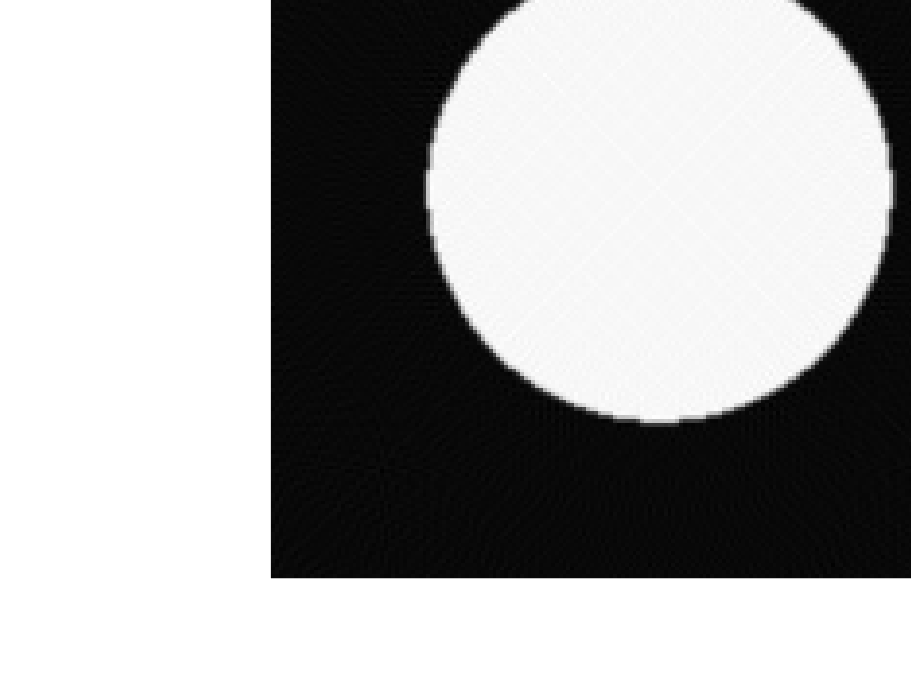


diskRecon = iradon(sinogram, theta, 'linear', 'Ram-Lak', 1, N);
figure, imshow(diskRecon,[]), title('FBP reconstruction')
saveFig("disk_reconstruction.png")

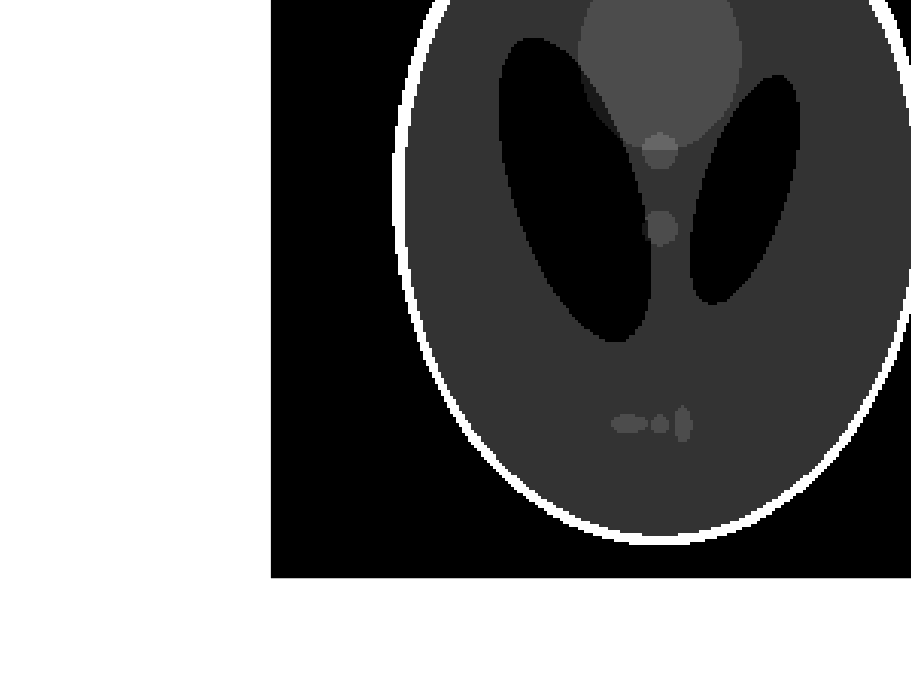


%% 4 · Shepp–Logan head phantom
P  = phantom(256);
th = 0:179;
[S, xp2] = radon(P, th);                      % get sinogram + radius vector
Pfbp = iradon(S, th, 'linear','Shepp-Logan', 1, size(P,1));

figure, imshow(P,[]), title('Shepp–Logan phantom')
saveFig("phantom_original.png")

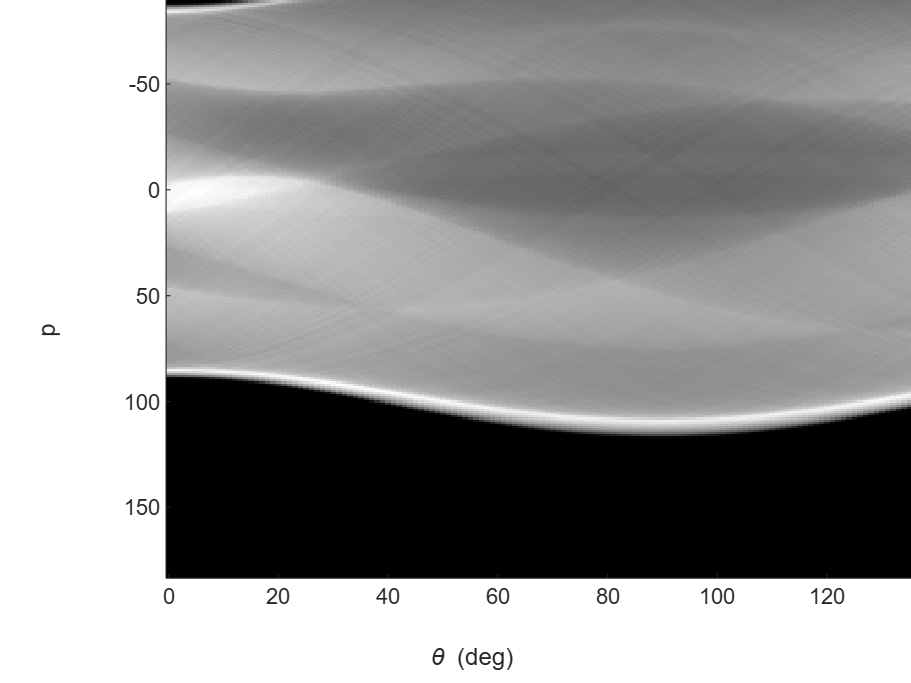


figure
imagesc(th, xp2, S); colormap(gray); axis tight
xlabel('\theta (deg)'), ylabel('p'), title('Phantom sinogram')
saveFig("phantom_sinogram.png")

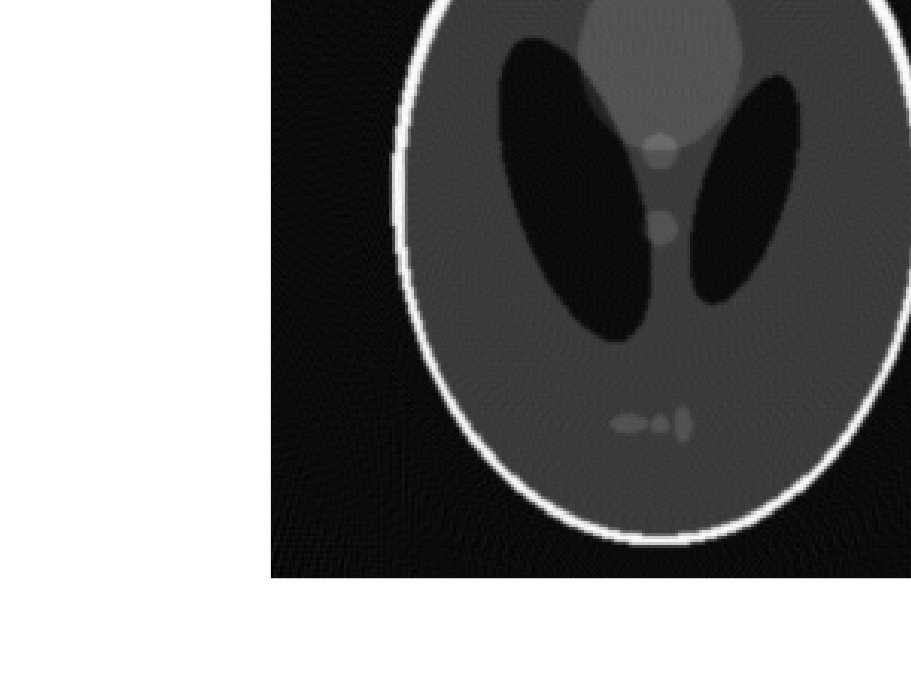


figure, imshow(Pfbp,[]), title('FBP reconstruction')
saveFig("phantom_reconstruction.png")

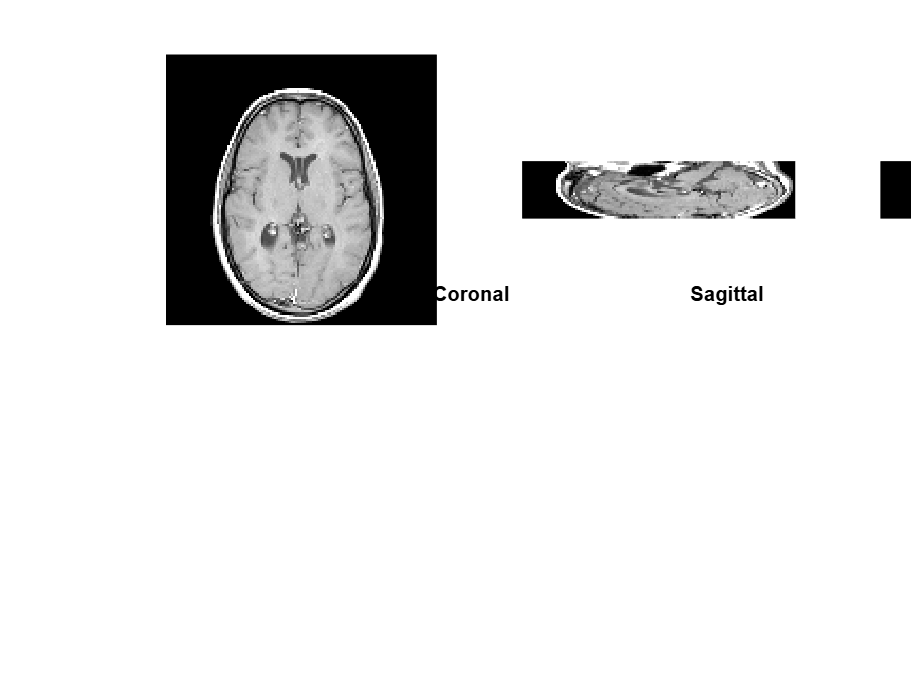

%% 5 · Built-in 3-D medical volume  (no download needed)

try
    % ---- Preferred: built-in kidney CT volume (Image Processing Toolbox) ----
    load kidneyVesselVolume  % gives variable 'kidneyVesselVolume'
    V = kidneyVesselVolume;  clear kidneyVesselVolume
    dataLabel = 'Kidney CT (built-in)';
catch
    % ---- Fallback: classic head MRI dataset ----
    load mri                 % variable 'D' is uint8 volume
    V = squeeze(D);          % remove singleton 4th dim
    dataLabel = 'Head MRI (built-in)';
end

% -- Show three orthogonal views --
mid = round(size(V)/2);
figure
subplot(1,3,1), imshow(squeeze(V(:,:,mid(3))),[]), title('Axial')
subplot(1,3,2), imshow(squeeze(V(:,mid(2),:))',[]), title('Coronal')
subplot(1,3,3), imshow(squeeze(V(mid(1),:,:))',[]), title('Sagittal')
sgtitle(dataLabel)
saveFig("mri_volume.png")